# Single Image Super-Resolution Using Deep Learning

このスクリプトは、以下のMATLAB公式ドキュメントを簡単に試すために、一部を修正したものです。基本的に内容は公式ドキュメントのものと同一です。

このスクリプトはこちらのブログ記事のために用意されました。

## 深層学習を使用した単一イメージ超解像処理：

https://jp.mathworks.com/help/images/single-image-super-resolution-using-deep-learning.html

clear;clc;close all
% ネットワークのロード
load('trainedVDSR-Epoch-100-ScaleFactors-234.mat');
% ネットワークの構造を可視化します
analyzeNetwork(net.Layers)

## テスト画像点の読み込み

- この時点では、高解像度な画像を読みこみ、さらに`imresize`により画像を縮小します

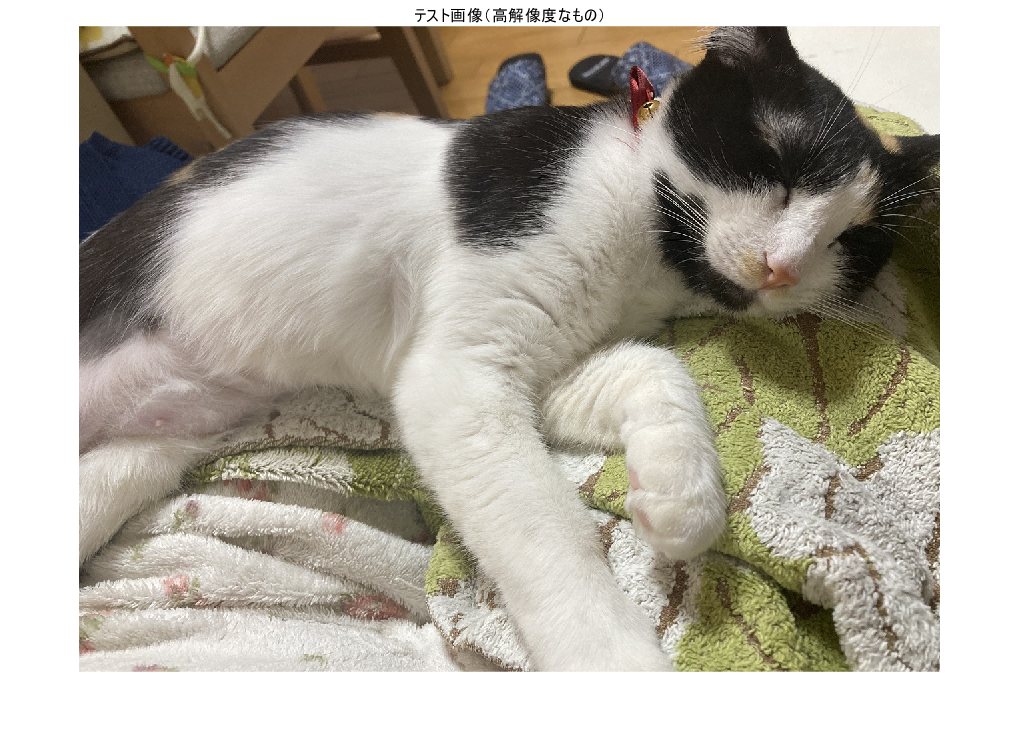

indx = 1; % Index of image to read from the test image datastore
Ireference = imread('myCat.JPG');
Ireference = im2double(Ireference);
imshow(Ireference)
title('テスト画像（高解像度なもの）')

## 画像の縮小

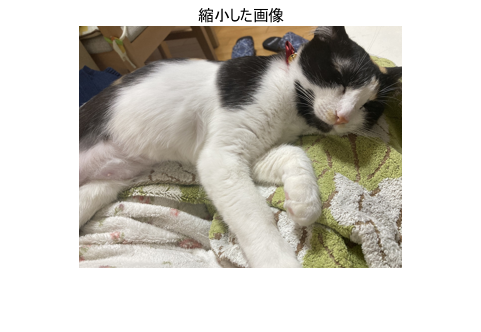

scaleFactor = 0.25;
Ilowres = imresize(Ireference,scaleFactor,'bicubic');
imshow(Ilowres)
title('縮小した画像')

## バイキュービック補間による拡大

- VDSRとの比較のためにバイキュービック補間により拡大します

[nrows,ncols,np] = size(Ireference);
Ibicubic = imresize(Ilowres,[nrows ncols],'bicubic');

## VDSRによる高解像度化

Iycbcr = rgb2ycbcr(Ilowres);
Iy = Iycbcr(:,:,1);
Icb = Iycbcr(:,:,2);
Icr = Iycbcr(:,:,3);
Iy_bicubic = imresize(Iy,[nrows ncols],'bicubic');
Icb_bicubic = imresize(Icb,[nrows ncols],'bicubic');
Icr_bicubic = imresize(Icr,[nrows ncols],'bicubic');

`activation`関数により計算

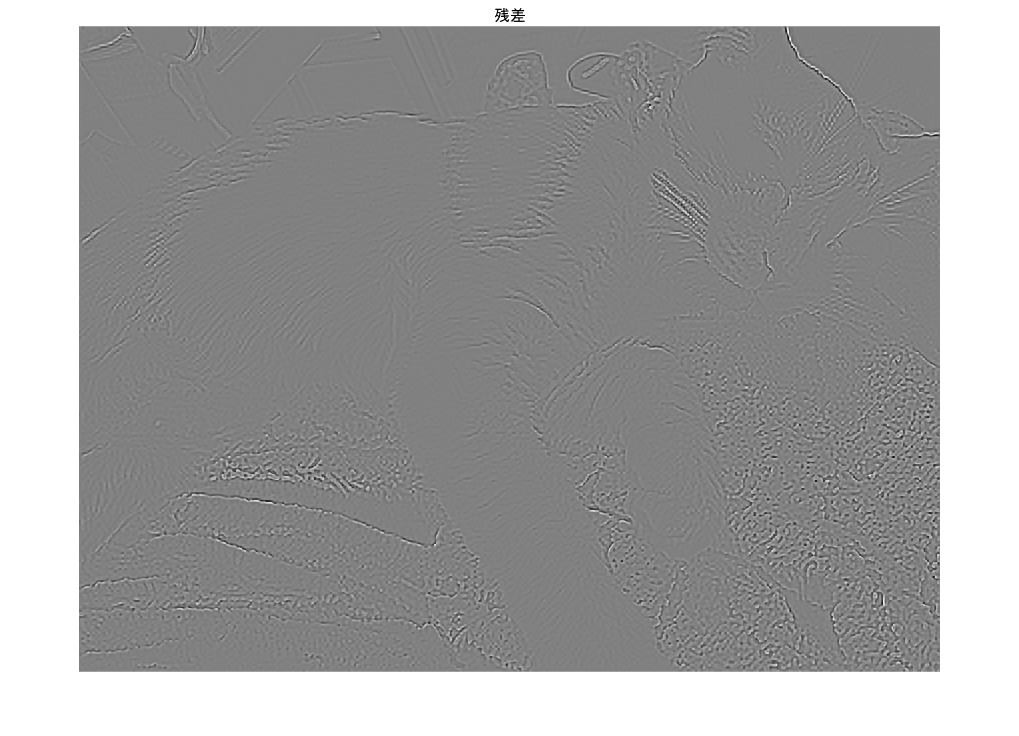

Iresidual = activations(net,Iy_bicubic,41);
Iresidual = double(Iresidual);
imshow(Iresidual,[])
title('残差')

高解像度化した画像を得るために足し算

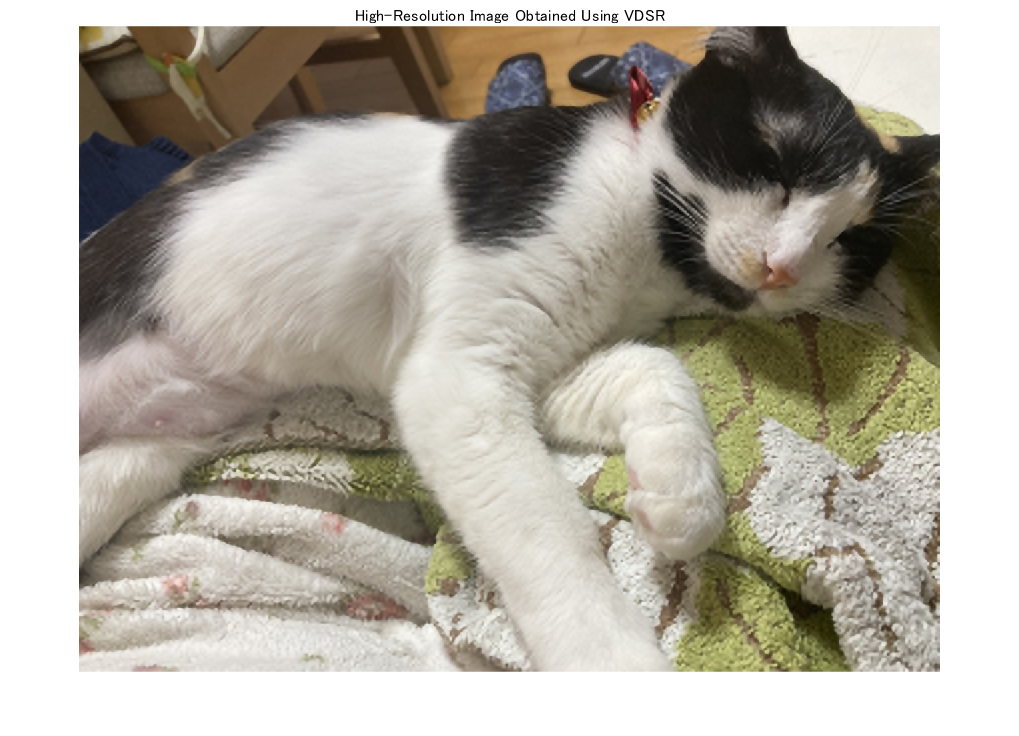

Isr = Iy_bicubic + Iresidual;
Ivdsr = ycbcr2rgb(cat(3,Isr,Icb_bicubic,Icr_bicubic));
figure;imshow(Ivdsr)
title('High-Resolution Image Obtained Using VDSR')

## 拡大して表示

roi = [320 30 480 400];

バイキュービック補間により拡大したもの（左）とVDSRによる結果（右）を比較します。VDSRのほうが、若干細かいところも高解像度化できている気もします。定量評価も行いましたが、ここでは割愛します。コードは以下のとおりです。

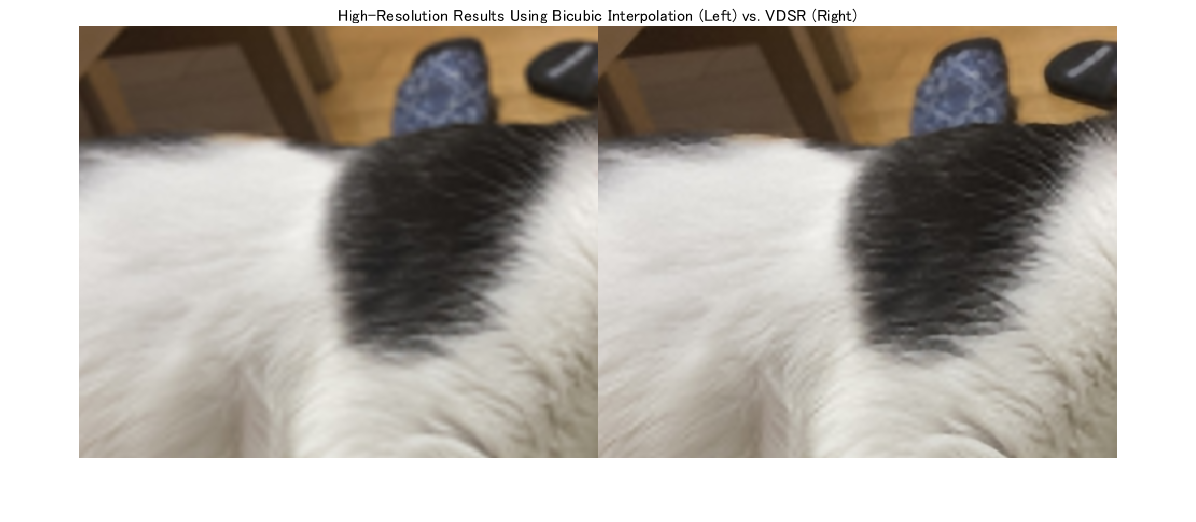

montage({imcrop(Ibicubic,roi),imcrop(Ivdsr,roi)})
title('High-Resolution Results Using Bicubic Interpolation (Left) vs. VDSR (Right)');

##  [`psnr`](docid:images_ref#bt5uhgi-1) 関数などによる定量評価

bicubicPSNR = psnr(Ibicubic,Ireference)

bicubicPSNR = 25.8240

vdsrPSNR = psnr(Ivdsr,Ireference)

vdsrPSNR = 26.0649

bicubicSSIM = ssim(Ibicubic,Ireference)

bicubicSSIM = 0.7729

vdsrSSIM = ssim(Ivdsr,Ireference)

vdsrSSIM = 0.7873

bicubicNIQE = niqe(Ibicubic)

bicubicNIQE = 5.1864

vdsrNIQE = niqe(Ivdsr)

vdsrNIQE = 5.1005

## References

[1] Kim, J., J. K. Lee, and K. M. Lee. "Accurate Image Super-Resolution Using Very Deep Convolutional Networks." *Proceedings of the IEEE**®** Conference on Computer Vision and Pattern Recognition*. 2016, pp. 1646-1654.

[2] Grubinger, M., P. Clough, H. Müller, and T. Deselaers. "The IAPR TC-12 Benchmark: A New Evaluation Resource for Visual Information Systems." *Proceedings of the OntoImage 2006 Language Resources For Content-Based Image Retrieval*. Genoa, Italy. Vol. 5, May 2006, p. 10.

[3] He, K., X. Zhang, S. Ren, and J. Sun. "Delving Deep into Rectifiers: Surpassing Human-Level Performance on ImageNet Classification." *Proceedings of the IEEE International Conference on Computer Vision*, 2015, pp. 1026-1034.